# How Do Differences in Certainty Compound for Various Evidence Integration Strategies?

Martynas Snarskis

## Setting Up the Problem

Decision-making has been very successfully modeled by Bayesian Inference models. We are interested in how differences in certainty over stimulus variables $X_i$ affect the certainty of the decision variable $R$ for various evidence integration strategies. Let $k$ represent the number of frames over which to combine stimulus, so that each trial of the task is represented by stimulus $X_{1...k}=\langle X_1,...,X_k \rangle$ where each $X_i \in \{0,1\}$is a binary random variable that represents the presence or absence of signal in that particular frame (this also generalizes to ). For simplicity, we assume correctly detecting each frame is equiprobable, so that $P(X_i | R) = \alpha$ for all $i\in \{1,...,k\}$. We also assume all priors are uninformative.

Using causal infernence (cross-modal cue combination), we can effectively increase the value of $\alpha$ for subjects -- a signature of performing approximate inference. For our purposes (creating a task in which we can use causal inference to reasonably maximize a subjects performance to measure), we're interested in how $P(R=r|X_{1...k})$ changes for a range of improvements of $\alpha$ for some $k$. 

The generality if this setup allows us to use combinatorics to describe all the different ways a subject can perceive/misperceive the stimulus in a trial. Letting $\alpha$ represent perceiving a frame and $(1-\alpha)$ represent misperceiving a frame, we have a *binomial exapansion of the trial outcomes:*


$$[\alpha + (1-\alpha)]^k = \alpha^k + {k\choose{1}}\alpha^{k-1}(1-\alpha) + \cdots + {k\choose{k-1}}\alpha(1-\alpha)^{k-1} + (1-\alpha)^k = 1$$


Note that this assumes each frame is equally perceptible, so we can't directly generalize to tasks in which *the amount* of signal in each frame changes significantly. Nonetheless, we can describe a number of task strucutures (corresponding to different integration strategies) using this setup. 

Each task consists of a set of stimuli $\mathbb{X}$(or stimuli parameters) in which each stimuli $X_{1...k}$ corresponds to a particular response $r\in R$. We can first partition the stimuli into classes based on their correct response, providing what we call the **response partition** $R_{=r}$. However, this does not capture the difficulty of different stimuli. As a simple example, consider a signal detection task, where subjects have to determine whether a particular signal appeared in at least one frame -- obviously stimuli in which the stimulus appears merely once is more difficult than when it appears in every frame. Correspondingly, these stimuli should have different trial outcomes, a different set of ways one can perceive/mispercieve the trial and still be correct, and resultingly a different summation expression describing the probability of answering correctly. Thus another way to partition stimuli is by their difficulty, or the **outcome partition**, which we refer to as a *stimuli class*. 

load("pfdri.mat")
alpha = movmean(alph,12);
a_imp = movmean(diff,12);

## Binary Word-Matching Task

In this task, the goal is to select the $r\in R \subset \{0,1\}^k$ such that $r=X_{1...k}$. Note that the number of possible choices $|R|$ grows exponentionally with the number of frames $k$, so that $|R|=2^k$. 

This task requires that the presence or absence of a stimulus is correctly detected in each frame. If the probability of detecting any single frame correct is $P(X_i|R)=\alpha$ then the probability of answering correctly is


$$P(R=r|X_{1...k})=\prod_{i=1}^k P(X_i|R) = \alpha^k$$


We postulate that this is the theoretically maximum rate of compounding improvement across frames during evidence integration in this general schema. It'd be interesting to try to prove this.

We can also determine the probability of choosing a particular incorrect answer. Let $\bar S_m$ refer to the class of stimuli that have $m$ frames mismatched between the correct choice $r_0=X_{1...k}$. For example, if all $X_i=0$, then $\bar S_1$ contains all choices $r_1$ such that each has exactly one $1$ in the vector (e.g. $\langle 1,0,0,... \rangle$or $\langle 0,1,0,0,... \rangle$). For any $r_m \in \bar S_m$, the probability of responding $r_m$ is 


$$P(R=r_m | X_{1...k}) = \alpha^{k-m} (1-\alpha)^m$$


Note that because $\alpha \geq 0.5$, we have $P(R=r_0|X_{1...k}) \geq ... \geq P(R=r_k|X_{1...k})$. That is, not all answers are equally wrong -- choosing an answer $r_k \in \bar S_k$ requires misperceiving every single frame, which is much less likely than misperceiving a single frame.

Were interested in seeing how the probability of answering correctly changes as we improve $\alpha$. 

K = 1:10; % num frames

bin_word = zeros(size(alpha,2),K(end));

% simulate
for k=K
	bin_word(:,k) = (alpha + a_imp).*k - alpha.*k;
end

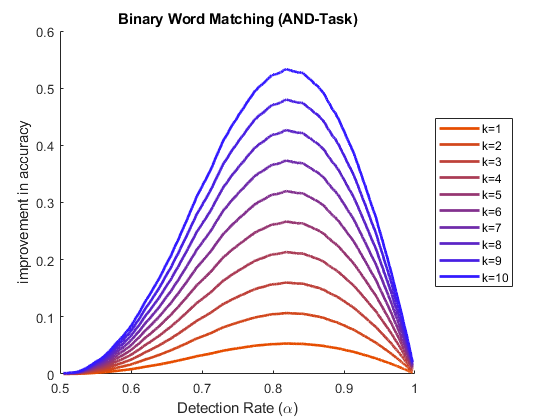

% plot
figure

% color gradient, index with K_COLOR(i,:)
K_COLOR = [linspace(.9,.2,k);linspace(.3,.1,k);linspace(0,1,k)]';

hold on

for k=K
    plot(alpha, bin_word(:,k), 'LineWidth', 2,...
		'DisplayName', sprintf('k=%d', k), 'Color', K_COLOR(k,:)); 
end
    
    title("Binary Word Matching (AND-Task)");
    xlabel("Detection Rate (\alpha)");
    ylabel("improvement in accuracy");
	legend('Location', 'eastoutside');
    
    xlim([0.5 1]);
    ylim([0, .6]);

hold off

Above we see how much of a boost in perforance (increase in probability of getting the correct answer) we can get from different per frame detection rate improvements (PFDRI). We see that as we increase the per frame detection rate the perfomance (on average) increases, as expected. As we increase $k$, we see the maximum improvement (with respect to baseline detection rates $\alpha$) increase as well. You may also notice that for small $\alpha$ (e.g. chance performance) the amount of improvement actually decreases with $k$...however, this is likely due to the fact performance overall decreases with $k$ for this task structure.

## Signal Detection Task

In this task, the goal is to determine whether a particular signal has been seen in any frame. This is a two-choice task, with $R=1$ corresponding to the presence of signal and $R=0$ representing the complete absence of the signal. We represent the presence of the relevent signal with $X_i=1$. Again, the probability of detecting the signal (or its absence) is assumed to be equiprobable per frame $P(X_i|R)=\alpha$. An example task would be to determine if any visual stimuli presented across frames is red (shapes can be red or blue). Note that for this task, the stimuli in each frame $X_i$ are not independant, even when conditioning on $R$ (unless $R=0$, in which case each frame MUST be $X_i=0$). 

We can partition the stimuli into classes $\bar X_{1...k}^s$ corresponding to the number of frames $s\in \{1,..,k\}$ that contain the relevant signal, so that $X_{1...k}^0$ corresponds to $R=0$, while all other values of $s$ correspond to $R=1$. Then the probability of choosing the correct answer $r$ ($r=1$if signal present in at least one frame and $r=0$ if not present in any frame) is


$$P(R|X_{1...k}^s) = 1 - [\alpha^{k-s}(1-\alpha)^s] = \alpha^k + \cdots + \left({k\choose{k-s}}-1\right)\alpha^{k-s}(1-\alpha)^s + \cdots + (1-\alpha)^k$$$


Intuitively, this equation states that there are $s$ specific frames (corresponding to $X_i=1$) that the subject has to misperceive in order to get the trial incorrect. In the case when there is no signal in the stimulus $s=0$, we have $P(R|X_{1...k}^0) =\alpha^k$ -- that is, the subjects has to perceive every frame correctly, otherwise they will (sans decision noise) answer incorrectly.

Again, we look at how improvements in per frame detection rates (PFDTI) compound to increase certainty in the decision. For simplicity, we only consider PFDTI of 0.1. As we see below, overall performance improvement (for all but $s=0$) decreases as we increases $s$ (the number of frames with the signal) as well as $k$.

K = 1:10; % num frames
s=1;

base_rate = repmat(alpha, size(K,2),1); % no PFDRI
sig_det = repmat(alpha+a_imp, size(K,2),1); % init P(R=r|X) matrix

% simulate
for k=K
	s=k;
    sig_det(k,:) = 1-(sig_det(k,:).^(k-s).*(1-sig_det(k,:)).^(k));
    base_rate(k,:) = 1-(base_rate(k,:).^(k-s).*(1-base_rate(k,:)).^(k));
end

total_improvement2 = sig_det - base_rate;

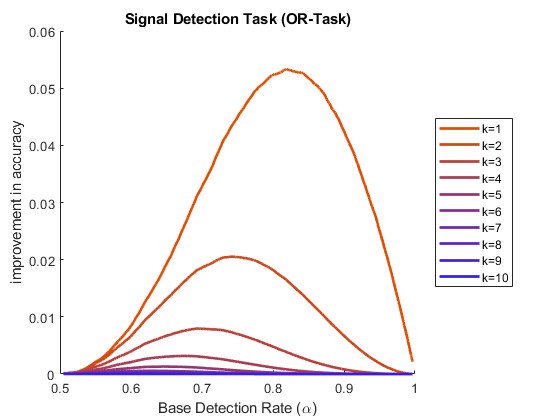

% plot
figure%('Position',[0,0,1000,600]);

% color gradient, index with K_COLOR(i,:)
K_COLOR = [linspace(.9,.2,K(end));linspace(.3,.1,K(end));linspace(0,1,K(end))]';

hold on

for k=1:10
    plot(alpha, total_improvement2(k,:), 'LineWidth', 2,...
		'DisplayName', sprintf('k=%d', k), 'Color', K_COLOR(k,:)); 
end


title("Signal Detection Task (OR-Task)");
xlabel("Base Detection Rate (\alpha)"); ylabel("improvement in accuracy");
legend('Location', 'eastoutside');

xlim([0.5 1]);
ylim([0 .06]);
%ylim([min(min(total_improvement2(s,:,:))) max(max(total_improvement2(s,:,:)))]);


hold off

## Majority Task

Consider the task of determining whether more tones came from the left $(R=0)$ side or the right $(R=1)$ side. For a series of $k$ frames (assumed to be odd for simplicity), we have $\lfloor k/2 \rfloor = (k-1)/2$ different stimulus classes $S_i$ where $i$ corresponds to the number of frames on the minority side (e.g. $S_0$ implies all frames from one side). Then the probability of answering correctly is a nasty sum...

## Even/Odd Task

Consider the task of determining whether there were an even or odd number of signals within the stimulus. This is a two-choice task, where $R=r_e$ corresponds to even number of signals and $R=r_o$ to an odd number. The probability of answering correctly


$$P(R=r|X_{1...k}) = \sum_{i=0}^{\left \lfloor \frac{k}{2} \right \rfloor} {k \choose 2i} \alpha^{k-2i} (1-\alpha)^{2i}$$


Note that for every misperceived frame the implied response switches from one answer to the other, such that misperceiving an even number of frames results in choosing the correct response. Furthermore, there are two stimulus classes which are described by the response partition, where stimuli corresponding to even number of signals $r_e$ with an even $k$ and similarly with $r_o$ with and odd $k$ form one stimulus class cluster, and vis a versa. 

evod = repmat(alpha,size(K,2),1); % init P(R=r|X) matrix

% simulate

for k=K
    temp1 = zeros(size(evod(k,:)));
	temp2 = zeros(size(evod(k,:)));
    
    for j=0:2:k
        temp1 = temp1 + (nchoosek(k,j) .* alpha.^(k-j) .* (1-alpha).^j);
		temp2 = temp2 + (nchoosek(k,j) .* (alpha+a_imp).^(k-j) .* (1-(alpha+a_imp)).^j);
    end
    evod(k,:) = temp2-temp1;
end

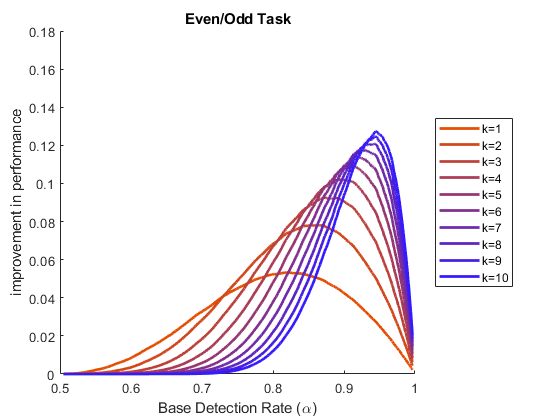

% plot
figure; hold on

% color gradient, index with K_COLOR(i,:)
K_COLOR = [linspace(.9,.2,K(end));linspace(.3,.1,K(end));linspace(0,1,K(end))]';

for k=K
	plot(alpha, evod(k,:), 'LineWidth', 2,...
		'DisplayName', sprintf('k=%d', k), 'Color', K_COLOR(k,:));
end

title("Even/Odd Task");
xlabel("Base Detection Rate (\alpha)");
ylabel("improvement in performance");
legend('Location', 'eastoutside'); 

xlim([0.5 1]);
ylim([0, .18]);

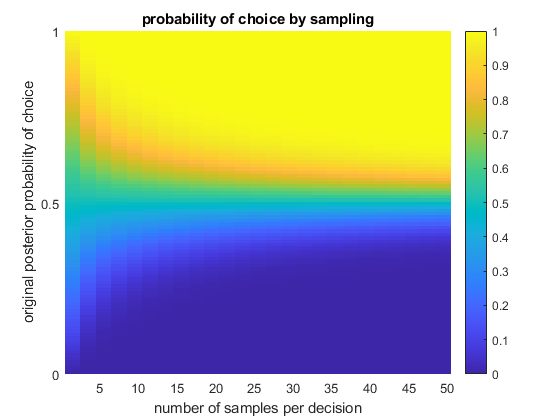

px=linspace(0,1,100);
ns=linspace(1,50,50);

ys = ones(50,100);

for i=1:50
	ys(i,:) = binocdf(floor(ns(i)/2),ns(i),px,'upper') + 0.5*binopdf(ns(i)/2,ns(i),px);
end

ys = [px(end:1);ys];

figure; hold on;
imagesc(ys',[0,1]);colorbar;
xlim([0.5,50.5])
ylim([0.5,100])
yticks([0.5,50,100]);yticklabels([0.0,0.5,1.0]);
ylabel("original posterior probability of choice");xlabel("number of samples per decision");
title("probability of choice by sampling");

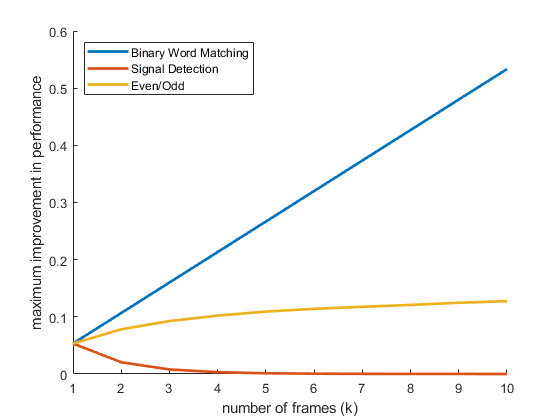

figure; hold on

plot(K,max(bin_word), 'LineWidth', 2,'DisplayName', 'Binary Word Matching')
plot(K,max(total_improvement2'), 'LineWidth', 2,'DisplayName', 'Signal Detection')
plot(K,max(evod'), 'LineWidth', 2,'DisplayName', 'Even/Odd')

xlabel("number of frames (k)");
ylabel("maximum improvement in performance");
legend('Location',"northwest")